# Homework 1

## Problem 1-5

**Question:** Derive the equations of motion of a pendulum balancing on a cart, and linearize them about the steady state $\bf{\theta = 0$ and $\bf{x = 0}$. Express the equations in state space form as $\bf{\dot{x} = Ax + Bu$ and $\bf{y = Cx}$

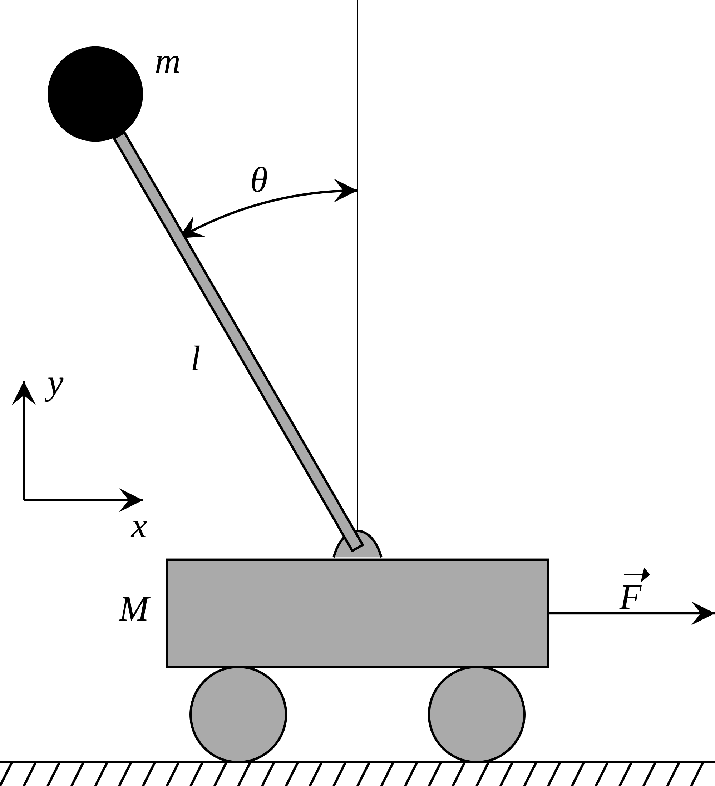




clc
close all
clear all

addpath Screws
addpath fcn_support
% Defining symbols
syms M m l i q di dq ddi ddq t force tau g C real
syms i0 q0 di0 dq0 ddi0 ddq0


 


P1 = [  i;
    0];

P2 = [  i - l*sin(q);
     l * cos(q)];

p_v = [i;q];
dp_v = [di;dq];
% 

% Taking derivative to compute velocities
V1 = get_vel(P1 ,p_v,dp_v);
V2 =get_vel(P2,p_v,dp_v);

% Computing Kinetic energy and potential energy
KE1 =simplify(1/2*M*V1'*V1);
KE2 =simplify(1/2*m*V2'*V2);

PE1 = M*g*P1(2);
PE2 = m*g*P2(2);

% Define Lagrangian
KE_total = KE1 + KE2;
PE_total = PE1 + PE2;



L = KE_total - PE_total;

[D,C,G] = get_mat(KE_total, PE_total, p_v,dp_v);
D = simplify(D);
C = simplify(C);
G = simplify(G);


% Now express this in the form of dx/dt = f(x,u)
Z = [i;q;di;dq]; % Vector of state space
ddZ0 = [0;0]; % Vector of SS accelerations [ddi0;ddq0]
Z0 = [0;0;0;0]; % Vector of SS  [i0;q0;di0;dq0]
force_tau = [force;0]; % Vector of force and torque
% Function to calculate Linearized representation
[A_lin,B_lin] = linearize_DCG(D,C,G,Z,force_tau,Z0,ddZ0);
A_lin = simplify(A_lin)

$$A\_lin = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & \frac{g\,m}{M} & 0 & 0\\ 0 & \frac{g\,\left(M+m\right)}{M\,l} & 0 & 0 \end{array}\right)$$

B_lin = simplify(B_lin)

$$B\_lin = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ \frac{1}{M} & 0\\ \frac{1}{M\,l} & 0 \end{array}\right)$$

## So we have

## 
$$\dot{Z} = \pmatrix{0&0&1&0 \cr 0&0&0&1 \cr 0&\frac{gm}{M}&0&0 \cr 0&\frac{g(M+m)}{Ml}&0&0}Z + \pmatrix{0 \cr 0 \cr \frac{1}{M} \cr \frac{1}{Ml}}u$$


## 
$$Y = \pmatrix{1&0&0&0 \cr 0&1&0&0}Z$$
